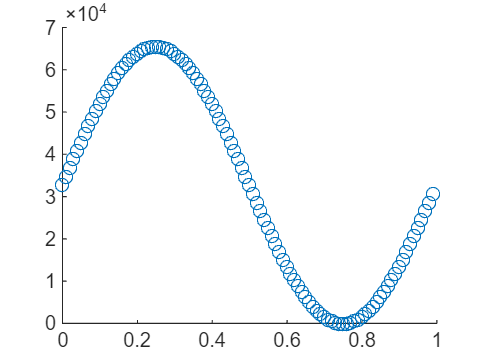

clear all

f = 1;
Vref = 3;
N = 16;
Vlsb = Vref/(2^N);
dt = 0.01;
t = [0:dt:1/f-dt];
y = floor(((sin(2*pi*f*t)+1)*1/2)*(2^N-1));
scatter(t,y)


hex_sine = dec2hex(y)

hex_sine = 100×4 char array
    '7FFF'
    '8808'
    '900A'
    '97FB'
    '9FD4'
    'A78D'
    'AF1E'
    'B67F'
    'BDA9'
    'C495'
    'CB3B'
    'D196'
    'D79E'
    'DD4D'
    'E29F'
    'E78C'
    'EC12'
    'F029'
    'F3D0'
    'F701'
    'F9BB'
    'FBF9'
    'FDBA'
    'FEFC'
    'FFBE'
    'FFFF'
    'FFBE'
    'FEFC'
    'FDBA'
    'FBF9'
    'F9BB'
    'F701'
    'F3D0'
    'F029'
    'EC12'
    'E78C'
    'E29F'
    'DD4D'
    'D79E'
    'D196'
    'CB3B'
    'C495'
    'BDA9'
    'B67F'
    'AF1E'
    'A78D'
    '9FD4'
    '97FB'
    '900A'
    '8808'
    '7FFF'
    '77F6'
    '6FF4'
    '6803'
    '602A'
    '5871'
    '50E0'
    '497F'
    '4255'
    '3B69'
    '34C3'
    '2E68'
    '2860'
    '22B1'
    '1D5F'
    '1872'
    '13EC'
    '0FD5'
    '0C2E'
    '08FD'
    '0643'
    '0405'
    '0244'
    '0102'
    '0040'
    '0000'
    '0040'
    '0102'
    '0244'
    '0405'
    '0643'
    '08FD'
    '0C2E'
    '0FD5'
    '13EC'
    '1872'
    '1D5F'
    '22B1'
    

MSB = bitshift(y,-8) 

MSB =    127   136   144   151   159   167   175   182   189   196   203   209   215   221   226   231   236   240   243   247   249   251   253   254   255   255   255   254   253   251   249   247   243   240   236   231   226   221   215   209   203   196   189   182   175   167   159   151   144   136


msb_sine = "0x"+string(dec2hex(MSB))

msb_sine = 100×1 string array
    "0x7F"
    "0x88"
    "0x90"
    "0x97"
    "0x9F"
    "0xA7"
    "0xAF"
    "0xB6"
    "0xBD"
    "0xC4"
    "0xCB"
    "0xD1"
    "0xD7"
    "0xDD"
    "0xE2"
    "0xE7"
    "0xEC"
    "0xF0"
    "0xF3"
    "0xF7"
    "0xF9"
    "0xFB"
    "0xFD"
    "0xFE"
    "0xFF"
    "0xFF"
    "0xFF"
    "0xFE"
    "0xFD"
    "0xFB"


lsb_sine = "0x"+string(dec2hex(y-MSB*2^8))

lsb_sine = 100×1 string array
    "0xFF"
    "0x08"
    "0x0A"
    "0xFB"
    "0xD4"
    "0x8D"
    "0x1E"
    "0x7F"
    "0xA9"
    "0x95"
    "0x3B"
    "0x96"
    "0x9E"
    "0x4D"
    "0x9F"
    "0x8C"
    "0x12"
    "0x29"
    "0xD0"
    "0x01"
    "0xBB"
    "0xF9"
    "0xBA"
    "0xFC"
    "0xBE"
    "0xFF"
    "0xBE"
    "0xFC"
    "0xBA"
    "0xF9"


reg = "0x"+string(dec2hex(ones(length(t),1)*8,2))

reg = 100×1 string array
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"
    "0x08"



mcu_sin = [reg,msb_sine,lsb_sine]

mcu_sin = 100×3 string array
    "0x08"    "0x7F"    "0xFF"
    "0x08"    "0x88"    "0x08"
    "0x08"    "0x90"    "0x0A"
    "0x08"    "0x97"    "0xFB"
    "0x08"    "0x9F"    "0xD4"
    "0x08"    "0xA7"    "0x8D"
    "0x08"    "0xAF"    "0x1E"
    "0x08"    "0xB6"    "0x7F"
    "0x08"    "0xBD"    "0xA9"
    "0x08"    "0xC4"    "0x95"
    "0x08"    "0xCB"    "0x3B"
    "0x08"    "0xD1"    "0x96"
    "0x08"    "0xD7"    "0x9E"
    "0x08"    "0xDD"    "0x4D"
    "0x08"    "0xE2"    "0x9F"
    "0x08"    "0xE7"    "0x8C"
    "0x08"    "0xEC"    "0x12"
    "0x08"    "0xF0"    "0x29"
    "0x08"    "0xF3"    "0xD0"
    "0x08"    "0xF7"    "0x01"
    "0x08"    "0xF9"    "0xBB"
    "0x08"    "0xFB"    "0xF9"
    "0x08"    "0xFD"    "0xBA"
    "0x08"    "0xFE"    "0xFC"
    "0x08"    "0xFF"    "0xBE"
    "0x08"    "0xFF"    "0xFF"
    "0x08"    "0xFF"    "0xBE"
    "0x08"    "0xFE"    "0xFC"
    "0x08"    "0xFD"    "0xBA"
    "0x08"    "0xFB"    "0xF9"


mcu_sin_reshaped = reshape(mcu_sin',1,[])

mcu_sin_reshaped = 1×300 string array
    "0x08"    "0x7F"    "0xFF"    "0x08"    "0x88"    "0x08"    "0x08"    "0x90"    "0x0A"    "0x08"    "0x97"    "0xFB"    "0x08"    "0x9F"    "0xD4"    "0x08"    "0xA7"    "0x8D"    "0x08"    "0xAF"    "0x1E"    "0x08"    "0xB6"    "0x7F"    "0x08"    "0xBD"    "0xA9"    "0x08"    "0xC4"    "0x95"    "0x08"    "0xCB"    "0x3B"    "0x08"    "0xD1"    "0x96"    "0x08"    "0xD7"    "0x9E"    "0x08"    "0xDD"    "0x4D"    "0x08"    "0xE2"    "0x9F"    "0x08"    "0xE7"    "0x8C"    "0x08"    "0xEC"    "0x12"    "0x08"    "0xF0"    "0x29"    "0x08"    "0xF3"    "0xD0"    "0x08"    "0xF7"    "0x01"    "0x08"    "0xF9"    "0xBB"    "0x08"    "0xFB"    "0xF9"    "0x08"    "0xFD"    "0xBA"    "0x08"    "0xFE"    "0xFC"    "0x08"    "0xFF"    "0xBE"    "0x08"    "0xFF"    "0xFF"    "0x08"    "0xFF"    "0xBE"    "0x08"    "0xFE"    "0xFC"    "0x08"    "0xFD"    "0xBA"    "0x08"    "0xFB"    "0xF9"    "0x08"    "0xF9"    "0xBB"    "0x08"    "0xF7"    "0x01"  


fid = fopen('dacSineWithReg.txt','wt');
fprintf(fid,"%s,",mcu_sin_reshaped);
fclose(fid);